Input figures

imagepath = 'MagnetConversions/CalibrationImage.bmp'

imagepath = 'MagnetConversions/CalibrationImage.bmp'


image_magnet = imread(imagepath);

# PX & MM

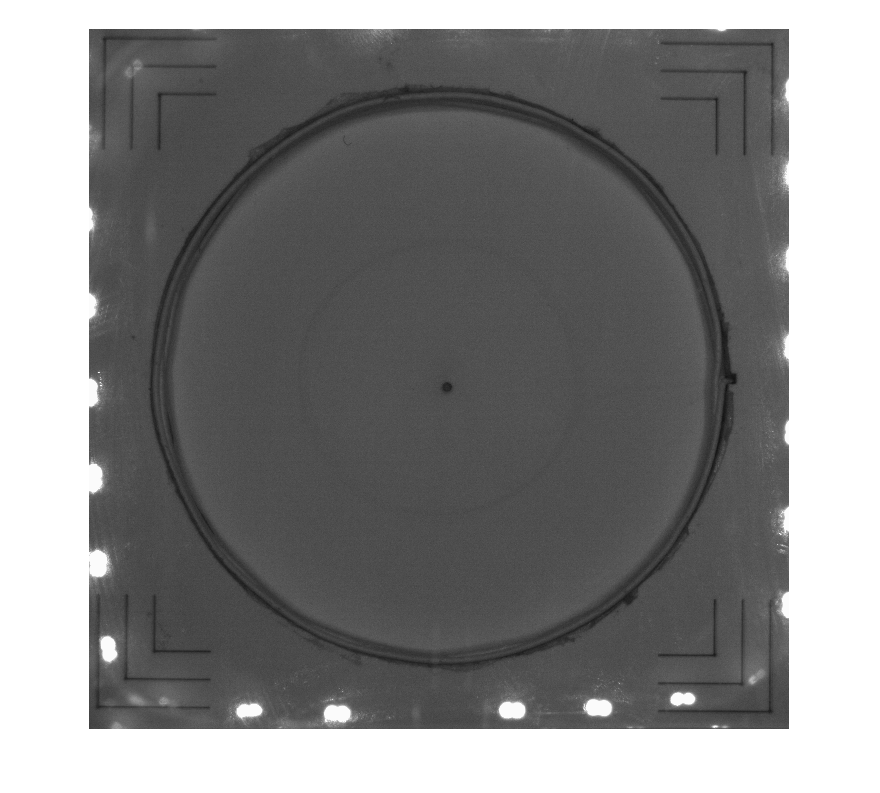

units = {'PX','MM'};

% Extract known points from image
clear checker
figure
imshow(image_magnet)
[checker(:,1),checker(:,2)] = getpts;

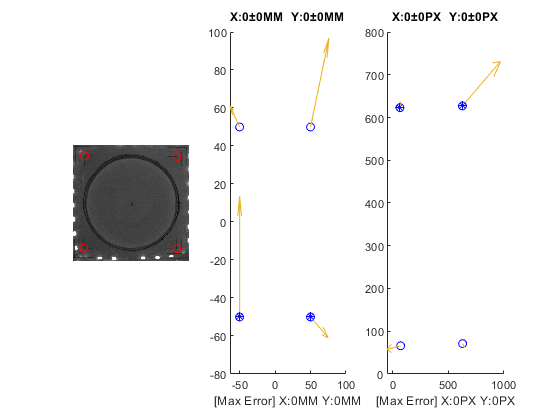

close

coord = [
    -50 -50;...
    50 -50;...
    50 50;...
    -50 50;...
    ];

% Get Transformation Matrix
PX2MM = homography_solve(checker', coord');
MM2PX = homography_solve(coord', checker');

% Save
dlmwrite(strcat('MagnetConversions/',units{1},'2',units{2},'.txt'),PX2MM);
dlmwrite(strcat('MagnetConversions/',units{2},'2',units{1},'.txt'),MM2PX);

plotHomographyResult(units,image_magnet,checker,coord,PX2MM,MM2PX)